%{
optimise.mlx
Uses wind turbine equations to calculate the optimal rotor design given input parameters.

Manually determine variables in `config` struct, variables in `params` will
be optimised automatically.

Assumptions:
    max_number_blades = 3
    max_rotor_radius = 0.5
    max_chord = 0.2
    visc_air = 15.06e-6
    C_D = 0 (for initial calculations)
    Chord distribution is linear

Callum Morrison, 2020
%}

clear

% Setup fixed optimisation values
config = struct( ...
    "N_elements", 30, ...                % Number of blade elements
    "rotor_start_radius", 0.12, ...      % Minimum blade radius
    "ratio_closeness", 0.5, ...          % Required closeness before blade convergence
    "ratio_closeness_halflife", 5, ...  % Number of iterations before ratio is halved
    "coefficient_drag", 0, ...           % Constant coefficient of drag
    "fluid_density", 1.225, ...          % Density of air
    "v_free_stream", 3, ...              % Velocity of wind tunnel
    "viscosity_kinematic", 15.06e-6 ...  % Viscosity of air
    );

load('S822_CL_Lookup.mat', "S822_CL_Lookup")
load('S822_Re_Values.mat', "S822_Re_Values")
load('S822_Alpha_Values.mat', "S822_Alpha_Values")

C_L_lookup = struct( ...
    "C_L", S822_CL_Lookup, ...
    "angle_of_attack", S822_Alpha_Values, ...
    "reynolds", S822_Re_Values ...
    );

population_size = 1000;

% Limit starting params somewhat (e.g. angle of attack). If best results
% come from a maximum or minimum value, it may be necessary to increase the
% range to find the optimal solution.
rotor_radius = rand([population_size, 1]) * (0.5 - 0.15) + 0.15;   % [0.15 0.5]
number_blades = randi(3, [population_size, 1]);                    % [1 2 3]
tip_speed_ratio = rand([population_size, 1]) * 4 + 1;              % [1 5]
angle_of_attack = deg2rad(rand([population_size, 1]) * 5 + 5);     % [5 10]
chord_root = rand([population_size, 1]) * (0.2 - 0.01) + 0.01;     % [0.01 0.2]
chord_tip = rand([population_size, 1]) * (0.2 - 0.01) + 0.01;      % [0.01 0.2]

C_P = zeros(population_size, 1);

% Initialise iteration variables
generation = 1;
max_generations = 60;
fitness = 0;
fitness_closeness = 0.1;
results = zeros([1, 8]);
halflife = 1;

while ~(all(fitness + fitness_closeness > 1) && all(fitness - fitness_closeness < 1)) && generation < max_generations
    
    % Increase ratio precision if needed
    if mod(generation, config.ratio_closeness_halflife) == 0
        config.ratio_closeness = config.ratio_closeness / 2;
        halflife = halflife + 1
    end
    
    % Calculate all outcomes for given parameters
    parfor i = 1:population_size
        temp_params = struct( ...
            "rotor_radius", rotor_radius(i), ...
            "number_blades", number_blades(i), ...
            "tip_speed_ratio", tip_speed_ratio(i), ...
            "angle_of_attack", angle_of_attack(i), ...
            "chord_root", chord_root(i), ...
            "chord_tip", chord_tip(i) ...
            );
        
        [data, C_P(i)] = solve_blade(config, temp_params, C_L_lookup);
    end
    
    % Replace NaN with 0; the worst score
    C_P(isnan(C_P)) = 0;
    
    % Combine solutions into a N * k matrix for easier manipulation
    population = [C_P, rotor_radius, number_blades, tip_speed_ratio, angle_of_attack, chord_root, chord_tip];
    
    % Rank solutions
    [~, order] = sort(C_P, 'descend');
    population = population(order, :);
    
    % Calculate variation in population
    variation = mean(var(rescale(population,'InputMin',min(population),'InputMax',max(population))));
    
    fprintf("Fitness: %0.4f\n", population(1, 1));
    fprintf("Variance: %0.4f\n", variation);
    
    results = [results; variation, population(1, :)];
    disp(population(1, 2:end));
    
    % Eliminate worst 1/2
    population = population(1:population_size / 2, :);
    
    % Crossover algirithm for new children
    parents = [randperm(population_size / 2)', randperm(population_size / 2)'];
    children = zeros([population_size, 6]);
    
    for i = 1:population_size / 2
        % Select parents
        parent = randi(2, [6, 1]);
        % parent_2 = mod(parent_1 - 2, 2) + 1
        
        child = parents(i, parent);
        genes = diag(population(child, 2:end));
        children(i, :) = genes';
    end

    % Mutation algorithm for remaining children
    for i = 1:population_size / 2
        % Generate mutations for each factor, average with the existing child
        % A weighted mean will bias towards the existing children with half life
        % Insert mutiated child back into children population
        children(i + population_size / 2, :) = [ ...
            mean([rand() * (0.5 - 0.15) + 0.15, repmat(children(i, 1), [1, halflife])]), ...
            round(mean([randi(3), repmat(children(i, 2), [1, halflife])])), ...
            mean([rand() * 4 + 1, repmat(children(i, 3), [1, halflife])]), ...
            mean([deg2rad(rand() * 5 + 5), repmat(children(i, 4), [1, halflife])]), ...
            mean([rand() * (0.2 - 0.01) + 0.01, repmat(children(i, 5), [1, halflife])]), ...
            mean([rand() * (0.2 - 0.01) + 0.01, repmat(children(i, 6), [1, halflife])]) ...
        ];
    end
    
    % Update original variables for next iteration
    rotor_radius = children(:, 1);
    number_blades = children(:, 2);
    tip_speed_ratio = children(:, 3);
    angle_of_attack = children(:, 4);
    chord_root = children(:, 5);
    chord_tip = children(:, 6);
    
    generation = generation + 1;
end

Fitness: 0.7993


Variance: 0.0880


    0.3064    3.0000    4.2826    0.1157    0.1926    0.0759



Fitness: 0.7121


Variance: 0.0688


    0.3064    3.0000    4.2826    0.1157    0.1926    0.0593



Fitness: 0.6607


Variance: 0.0574


    0.2433    3.0000    3.2228    0.1498    0.1604    0.0682



Fitness: 0.6777


Variance: 0.0519


    0.2756    3.0000    3.8790    0.1184    0.1711    0.0774



halflife = 2

Fitness: 0.5642


Variance: 0.0525


    0.3978    3.0000    3.4099    0.1582    0.1582    0.0640



Fitness: 0.5537


Variance: 0.0478


    0.2704    3.0000    2.7431    0.1298    0.1921    0.1193



Fitness: 0.5670


Variance: 0.0432


    0.3640    3.0000    2.9671    0.1710    0.1668    0.0785



Fitness: 0.5669


Variance: 0.0417


    0.3539    3.0000    3.1522    0.1483    0.1672    0.0860



Fitness: 0.5930


Variance: 0.0400


    0.3413    3.0000    3.1104    0.1416    0.1902    0.0958



halflife = 3

Fitness: 0.5451


Variance: 0.0433


    0.3397    3.0000    3.4107    0.1389    0.1681    0.0699



Fitness: 0.5310


Variance: 0.0490


    0.3251    2.0000    3.7097    0.1366    0.1657    0.0865



Fitness: 0.5301


Variance: 0.0480


    0.3636    3.0000    3.2924    0.1330    0.1683    0.0878



Fitness: 0.5404


Variance: 0.0484


    0.3742    2.0000    3.7059    0.1424    0.1802    0.0882



Fitness: 0.5411


Variance: 0.0456


    0.3618    2.0000    3.6618    0.1424    0.1802    0.0882



halflife = 4

Fitness: 0.5113


Variance: 0.0493


    0.3848    2.0000    3.5318    0.1373    0.1857    0.0959



Fitness: 0.5150


Variance: 0.0434


    0.3677    2.0000    3.9670    0.1518    0.1512    0.0673



Fitness: 0.5161


Variance: 0.0396


    0.3561    2.0000    3.4724    0.1428    0.1877    0.0869



Fitness: 0.5168


Variance: 0.0390


    0.3561    2.0000    3.4724    0.1428    0.1877    0.0873



Fitness: 0.5111


Variance: 0.0417


    0.3964    2.0000    3.8247    0.1516    0.1460    0.0834



halflife = 5

Fitness: 0.5090


Variance: 0.0402


    0.3964    2.0000    3.8247    0.1516    0.1460    0.0834



Fitness: 0.5080


Variance: 0.0391


    0.3673    2.0000    3.7309    0.1428    0.1599    0.0843



Fitness: 0.4987


Variance: 0.0392


    0.3493    2.0000    3.4019    0.1505    0.1660    0.0931



Fitness: 0.5094


Variance: 0.0339


    0.3806    2.0000    3.3187    0.1527    0.1726    0.0993



Fitness: 0.5032


Variance: 0.0373


    0.3522    2.0000    3.7016    0.1430    0.1549    0.0831



halflife = 6

Fitness: 0.5062


Variance: 0.0371


    0.3806    2.0000    3.3187    0.1527    0.1726    0.0997



Fitness: 0.5010


Variance: 0.0355


    0.3526    2.0000    3.6991    0.1497    0.1488    0.0797



Fitness: 0.5010


Variance: 0.0372


    0.3526    2.0000    3.6991    0.1497    0.1488    0.0797



Fitness: 0.5014


Variance: 0.0393


    0.3749    2.0000    3.4947    0.1501    0.1554    0.0901



Fitness: 0.5069


Variance: 0.0353


    0.3607    2.0000    3.5283    0.1516    0.1694    0.0798



halflife = 7

Fitness: 0.5047


Variance: 0.0397


    0.3607    2.0000    3.5283    0.1495    0.1694    0.0798



Fitness: 0.5034


Variance: 0.0398


    0.3749    2.0000    3.7792    0.1434    0.1607    0.0850



Fitness: 0.4988


Variance: 0.0405


    0.3520    2.0000    3.4052    0.1449    0.1727    0.0928



Fitness: 0.5029


Variance: 0.0346


    0.3672    2.0000    3.7185    0.1488    0.1469    0.0781



Fitness: 0.5018


Variance: 0.0393


    0.3756    2.0000    3.5925    0.1402    0.1698    0.0876



halflife = 8

Fitness: 0.5053


Variance: 0.0393


    0.3756    2.0000    3.5925    0.1474    0.1698    0.0889



Fitness: 0.5016


Variance: 0.0356


    0.3773    2.0000    3.6793    0.1486    0.1531    0.0882



Fitness: 0.5025


Variance: 0.0354


    0.3695    2.0000    3.4785    0.1540    0.1532    0.0857



Fitness: 0.5021


Variance: 0.0385


    0.3529    2.0000    3.7050    0.1458    0.1626    0.0739



Fitness: 0.5021


Variance: 0.0357


    0.3742    2.0000    3.5500    0.1459    0.1626    0.0874



halflife = 9

Fitness: 0.5030


Variance: 0.0396


    0.3684    2.0000    3.6518    0.1412    0.1649    0.0864



Fitness: 0.5040


Variance: 0.0376


    0.3864    2.0000    3.6183    0.1525    0.1486    0.0843



Fitness: 0.5029


Variance: 0.0385


    0.3864    2.0000    3.6183    0.1443    0.1661    0.0843



Fitness: 0.5036


Variance: 0.0395


    0.3719    2.0000    3.6703    0.1457    0.1565    0.0830



Fitness: 0.5021


Variance: 0.0363


    0.3656    2.0000    3.4777    0.1512    0.1584    0.0865



halflife = 10

Fitness: 0.5029


Variance: 0.0343


    0.3612    2.0000    3.5254    0.1477    0.1662    0.0856



Fitness: 0.5040


Variance: 0.0336


    0.3659    2.0000    3.4762    0.1507    0.1648    0.0861



Fitness: 0.5040


Variance: 0.0324


    0.3659    2.0000    3.4762    0.1507    0.1648    0.0861



Fitness: 0.5056


Variance: 0.0342


    0.3699    2.0000    3.5937    0.1479    0.1641    0.0852



Fitness: 0.5042


Variance: 0.0361


    0.3787    2.0000    3.6235    0.1451    0.1625    0.0850



halflife = 11

Fitness: 0.5056


Variance: 0.0333


    0.3699    2.0000    3.4413    0.1515    0.1712    0.0879



Fitness: 0.5038


Variance: 0.0335


    0.3591    2.0000    3.6757    0.1472    0.1602    0.0786



Fitness: 0.5043


Variance: 0.0351


    0.3681    2.0000    3.6300    0.1437    0.1657    0.0853



Fitness: 0.5036


Variance: 0.0330


    0.3686    2.0000    3.5125    0.1500    0.1614    0.0879



Fitness: 0.5041


Variance: 0.0312


    0.3688    2.0000    3.6490    0.1442    0.1629    0.0829



halflife = 12

Fitness: 0.5049


Variance: 0.0315


    0.3674    2.0000    3.5764    0.1478    0.1674    0.0853



Fitness: 0.5041


Variance: 0.0322


    0.3624    2.0000    3.4952    0.1508    0.1673    0.0835



Fitness: 0.5043


Variance: 0.0296


    0.3801    2.0000    3.7708    0.1393    0.1615    0.0853



Fitness: 0.5039


Variance: 0.0306


    0.3675    2.0000    3.5187    0.1489    0.1658    0.0882



Fitness: 0.5071


Variance: 0.0298


    0.3801    2.0000    3.7708    0.1472    0.1641    0.0819



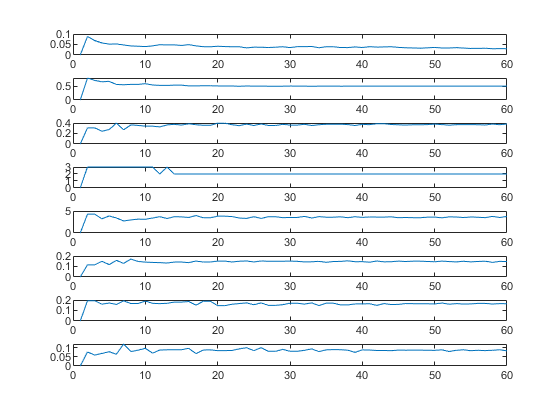


for i = 1:size(results, 2)
    subplot(size(results, 2), 1, i)
    plot(results(:, i));
end



% % Check that Betz limit has not been surpassed
% C_P = 4 .* data.axial_induction_factor .* (1 - data.axial_induction_factor).^2;
% 
% if max(C_P) > 0.593
%     error("The Betz limit has been exceeded. Check your calculations.")
% else
%     fprintf("Best coefficient of power is %1.3f", max(C_P))
% end
